format short % long for 15 sig figs, change to short for 4 sig figs


## SES

#### UTS*Area load cases 

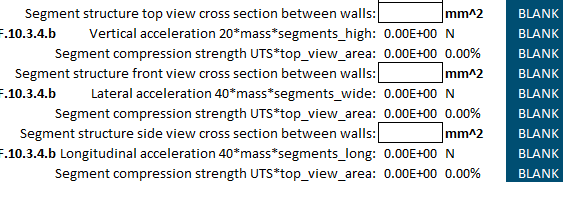

#### Module Volume

[https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf](https://enepaq.com/wp-content/uploads/2023/09/VTC6-Sony-Murata-Li-ion-Battery-Module-With-Temperature-Sensor-Datasheet-Tesla-Battery-Sponsorship-Formula-SAE-Electric-Formula-Student-Battery-Pack.pdf) 

These represent the dimensions  of 1 battery module(picture below). Variables are used for other calculations

EneModWidth = 20.3/1000%(m)

EneModWidth = 0.0203

EneSegHeight =  105.6/1000%(m)

EneSegHeight = 0.1056

EneModDepth = 69.5/1000%(m)

EneModDepth = 0.0695

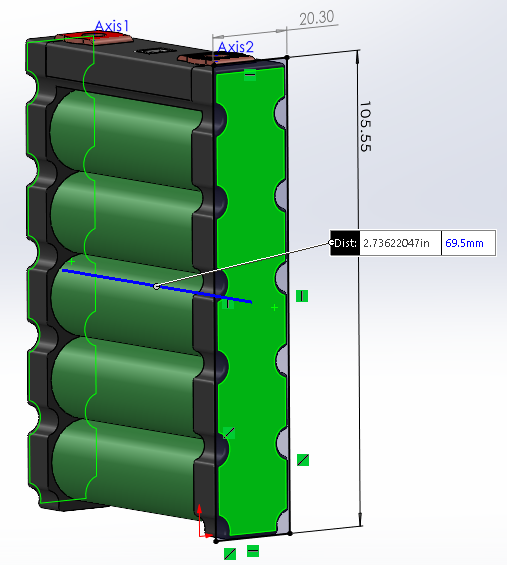

ModuleWeight = 278/1000%kg(aka 278g)

ModuleWeight = 0.2780

### Segment Dimensions

SegmentCasingHeight = EneSegHeight%m(Segment Height is pretty much the height of one module)

SegmentCasingHeight = 0.1056

EneSegmentDepth = 6*EneModDepth%num moduleSs*moduleDepth*mmtoinches + flange added length - hole location

EneSegmentDepth = 0.4170

EneSegmentWidth = EneModWidth * 4% rough width of segment

EneSegmentWidth = 0.0812

garoliteThickness = (1/16)*25.4/1000%m

garoliteThickness = 0.0016

SegmentModulesWeight = ModuleWeight*23%kg

SegmentModulesWeight = 6.3940

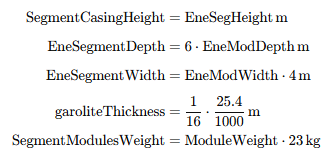

### Segment Cross Sectional Areas

TopCrossSecArea = EneSegmentDepth*garoliteThickness*2;
WidthCrossSecArea = EneSegmentDepth*garoliteThickness*2;
DepthCrossSecArea = EneSegmentWidth*garoliteThickness*2 + EneSegHeight*garoliteThickness*2;
airHoleDia = 8/1000;%m

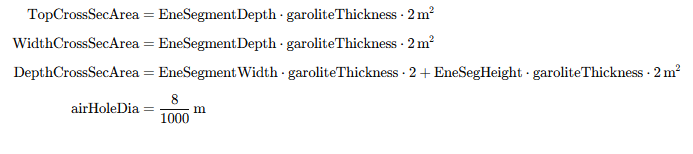

### Tab Gluing Strength

Pload = 9.8*20*SegmentModulesWeight

Pload = 1.2532e+03

insetlength = 26.75/1000%m

insetlength = 0.0267

bolttosegmentlength = 14/1000%m

bolttosegmentlength = 0.0140

L1 = 14/1000%m

L1 = 0.0140

L2 = 40.75/1000%m

L2 = 0.0408

P1 = -(Pload*L2)/(L2-L1)

P1 = -1.9091e+03

P2 = (Pload*L1)/(L2-L1)

P2 = 655.8929

Mc = Pload*L2 - P1*(L2-L1)

Mc = 102.1378

Medge = -Pload*L1 + Mc

Medge = 84.5926

Stress_bending = (Medge*(garoliteThickness/2))/(4*garoliteThickness*garoliteThickness^3)/12

Stress_bending = 2.2025e+08

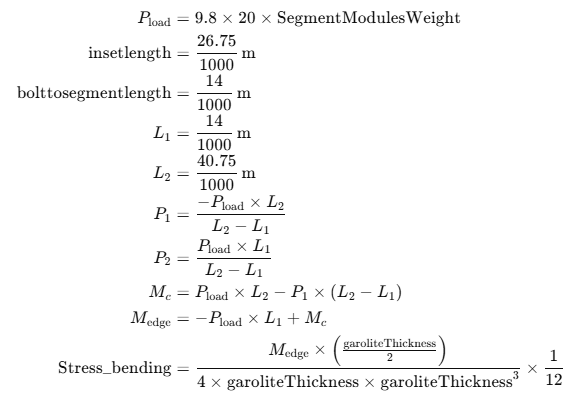

### Lid (Polycarbonate) Properties

polycarbonateThickness = 1/4*25.4/1000

polycarbonateThickness = 0.0063

### Lid Strength

Polycarbonate properties [https://www.matweb.com/search/DataSheet.aspx?MatGUID=501acbb63cbc4f748faa7490884cdbca](https://www.matweb.com/search/DataSheet.aspx?MatGUID=501acbb63cbc4f748faa7490884cdbca) 

Ma = (Pload*EneSegmentDepth^2)/12

Ma = 18.1602

Stress_bending = (Ma*(polycarbonateThickness/2))/(polycarbonateThickness^3*(EneSegmentWidth)/12)

Stress_bending = 3.3279e+07

PolycarbonateStrength = 62000000;
SfLid = PolycarbonateStrength/Stress_bending

SfLid = 1.8630

PolycarbonateFlexuralModulus = 2228000000

PolycarbonateFlexuralModulus = 2.2280e+09

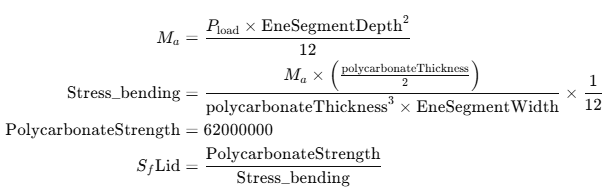

### Lid Deflection from 20g Loading

Packload = TopCrossSecForce ;
EneLidSegmentDepth = 6*EneModDepth + 0.082 -0.022;%
vmax = Packload * (EneLidSegmentDepth^4)/384/(PolycarbonateFlexuralModulus)/(((EneSegmentWidth)*polycarbonateThickness^3)/12)

vmax = 0.0438

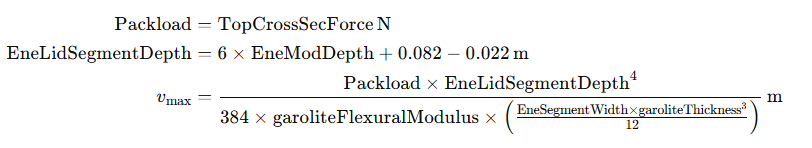

### Garolite Properties

psiTopPascal = 6894.76;
garoliteStrength = 38000*psiTopPascal;%262,000,000pa
garoliteFlexuralModulus = 2400* 1000 * psiTopPascal

garoliteFlexuralModulus = 1.6547e+10

### Segment Forces and Stresses

TopCrossSecForce = SegmentModulesWeight*20*9.8%newtons

TopCrossSecForce = 1.2532e+03

WidthCrossSecForce = 6*SegmentModulesWeight*40*9.8;%newtons
DepthCrossSecForce = SegmentModulesWeight * 40 * 9.8;%newtons

TopStress = TopCrossSecForce/TopCrossSecArea%pa

TopStress = 9.4656e+05

WidthStress = WidthCrossSecForce/WidthCrossSecArea%pa

WidthStress = 1.1359e+07

DepthStress = DepthCrossSecForce/DepthCrossSecArea%pa

DepthStress = 4.2261e+06

SafetyFactorCasing = garoliteStrength/WidthStress%pa

SafetyFactorCasing = 23.0660

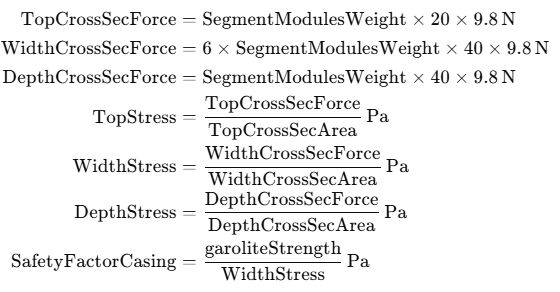

### Vertical Minimum Column Properties

vmincolumnlength = EneSegmentWidth*1000%mm

vmincolumnlength = 81.2000

vmincolumnarea = (garoliteThickness*EneSegHeight - 5*airHoleDia*garoliteThickness)*1000^2%mm^2

vmincolumnarea = 104.1400

vmincolumnMOI = ((garoliteThickness^3*(EneSegmentWidth-5*airHoleDia))/12)*1000^4%mm^4

vmincolumnMOI = 13.7359

vPcrEuler = (pi^2*garoliteFlexuralModulus*vmincolumnMOI)/vmincolumnlength^2

vPcrEuler = 3.4023e+08

stress_compressive = TopCrossSecForce/(vmincolumnarea/1000^2)

stress_compressive = 1.2034e+07

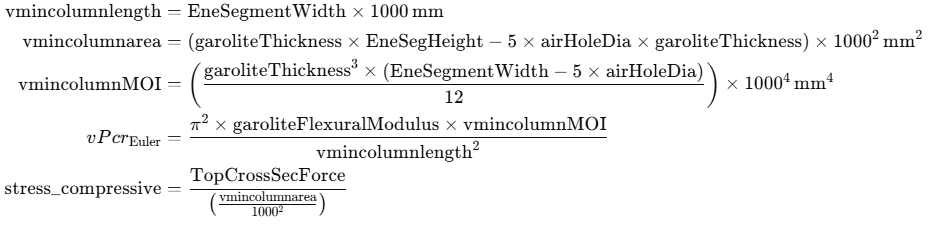

### Lateral Minimum Column Properties

lmincolumnlength = EneSegmentDepth*1000%mm

lmincolumnlength = 417.0000

lmincolumnarea = (garoliteThickness*(EneSegmentWidth+2*garoliteThickness))*1000^2%mm^2

lmincolumnarea = 133.9453

lmincolumnMOI = ((garoliteThickness^3*(EneSegmentWidth+2*garoliteThickness))/12)*1000^4%mm^4

lmincolumnMOI = 28.1303

### 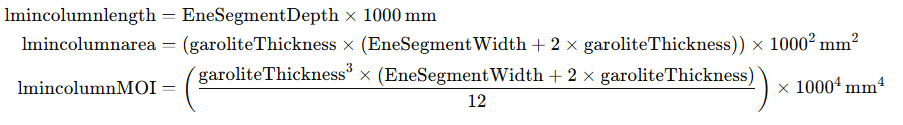

### Bolt calculations

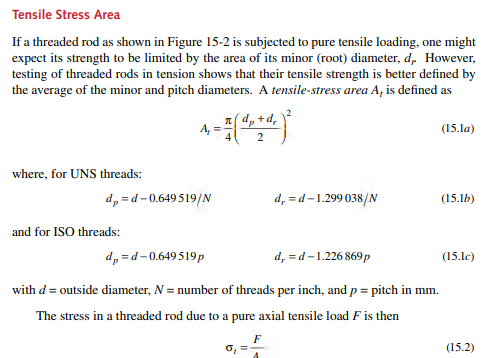

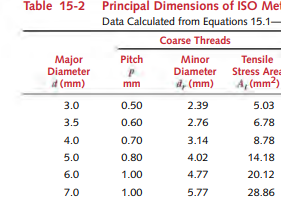

dia = 6;
pitch = 1;
diaPitch = dia - 0.649519*pitch;%mm 
diaRoot = dia - 1.226869*pitch ;%mm
AreaBoltTensile = pi/4*((diaPitch+diaRoot)/2)^2;%in mm^2
ABTMeters = AreaBoltTensile/1000000;%Converts to Meters
exampleGr5Tensile = 827370875;%Converted from psi
MaxTensileForFastener = exampleGr5Tensile*ABTMeters %newtons

MaxTensileForFastener = 1.6649e+04

SafetyFactorBoltTension = MaxTensileForFastener*2/TopCrossSecForce%assumes all load is on one side of segment

SafetyFactorBoltTension = 26.5707

SafetyFactorVoltShear = MaxTensileForFastener*2/WidthCrossSecForce%Assumes 

SafetyFactorVoltShear = 2.2142

% no preload friction an only one side

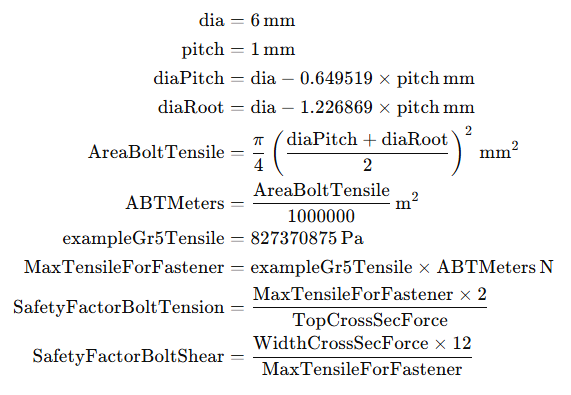

### Tear out 

[https://laminatedplastics.com/g-10.pdf](https://laminatedplastics.com/g-10.pdf) 

BoltDistanceFromEdge = 8/1000;%mm  realistic distance from edge
maxTearoutForce = BoltDistanceFromEdge*garoliteThickness*garoliteStrength

maxTearoutForce = 3.3274e+03

### Flange Bonding(Pure Pull)

fr4BondStrength = 2200*psiTopPascal;
MinFlangeBondArea = DepthCrossSecForce/fr4BondStrength

MinFlangeBondArea = 1.6524e-04

DepthRestrictingBondArea = garoliteThickness * 80/1000

DepthRestrictingBondArea = 1.2700e-04

SideBondArea = 0.02* garoliteThickness*2

SideBondArea = 6.3500e-05

bondMaxForce = fr4BondStrength * (DepthRestrictingBondArea + SideBondArea)

bondMaxForce = 2.8896e+03

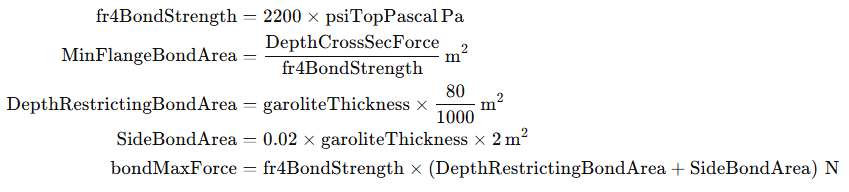

## Euler-Johnson buckling limits

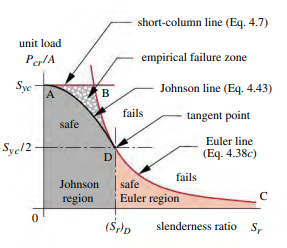

MomentOfInertiaSideWalls = 2*( (EneSegmentWidth/2+garoliteThickness/2)^2 * garoliteThickness*(EneSegHeight+(2*garoliteThickness))) + (garoliteThickness^3*SegmentCasingHeight/12)

MomentOfInertiaSideWalls = 5.9179e-07

% half width to get to walls + half of garolite thickness = centroid
% distance away, * area sidewall + garolite thickness^3(height) * segment height(width) 

MomentOfInertiaBottom = (garoliteThickness/2 + EneSegHeight/2)^2 * garoliteThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)

MomentOfInertiaBottom = 3.7028e-07

MomentOfInertiaLid = (garoliteThickness/2 + EneSegHeight/2+(15/1000))^2 * garoliteThickness*EneSegmentWidth + (garoliteThickness^3*EneSegmentWidth/12)

MomentOfInertiaLid = 6.0654e-07


ixx = MomentOfInertiaLid + MomentOfInertiaBottom + MomentOfInertiaSideWalls

ixx = 1.5686e-06

RadiusOfGyration = sqrt(ixx/DepthCrossSecArea)

RadiusOfGyration = 0.0514


SlendernessRatioCasing = EneSegmentDepth/RadiusOfGyration

SlendernessRatioCasing = 8.1085

SlendernessRatioForHalfStrength = pi*sqrt(2*garoliteFlexuralModulus/garoliteStrength)

SlendernessRatioForHalfStrength = 35.3085

MaxForceJohnson = DepthCrossSecArea *(garoliteStrength-(1/garoliteFlexuralModulus *(garoliteStrength*SlendernessRatioCasing/2/pi)^2))

MaxForceJohnson = 1.5129e+05

SFJohnson = MaxForceJohnson/WidthCrossSecForce

SFJohnson = 10.0602

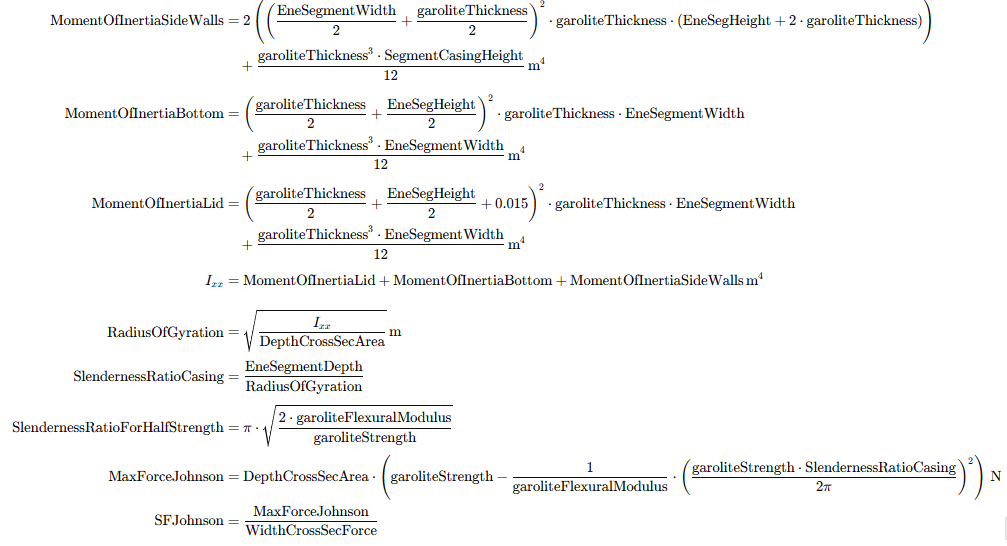

### Passive Thermal Properties

SurfaceArea = EneSegmentDepth*EneSegmentWidth*2 + EneSegHeight*EneSegmentDepth*2;
WattsPerKelvin = 1/garoliteThickness * 0.288 * SurfaceArea % W/m/K * m^2 /m = w/k

WattsPerKelvin = 28.2632